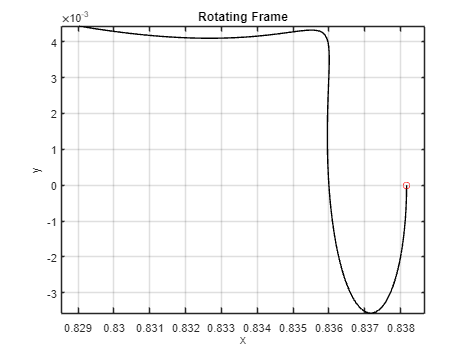

global FORWARD tol mu
FORWARD = 1;
tol = 1e-8;

mu = 0.0121; % Earth-Moon system
% Equation of motion for points along the axis
poly1 = [1  -1*(3-mu)  (3-2*mu)  -mu   2*mu  -mu];

rt1 = roots(poly1);
for k = 1:5
    if isreal(rt1(k)) 
        gamma = rt1(k);
    end
end

xL = (1 - mu) - gamma;

T = 2 * pi; % Period of primaries in non-dimensional units

% L1 eigenbasis
mubar = mu / abs(xL - 1 + mu)^3 + (1 - mu) / abs(xL + mu)^3;
a = 1 + 2 * mubar;
b = mubar - 1;

lam = sqrt(0.5 * (mubar - 2 + sqrt(9 * mubar^2 - 8 * mubar)));
nu = sqrt(-0.5 * (mubar - 2 - sqrt(9 * mubar^2 - 8 * mubar)));

sigma = 2 * lam / (lam^2 + b);
tau = -(nu^2 + a) / (2 * nu);

u1 = [1; -sigma; lam; -lam * sigma];
u2 = [1; sigma; -lam; -lam * sigma];
u = [1; 0; 0; nu * tau];
v = [0; tau; -nu; 0];

% Compute small periodic orbit (planar Lyapunov orbit)
tfinal = 2 * pi / nu;
tspan = 0:0.001 * T:tfinal;
XL = [xL; 0; 0; 0];

displacement = 1e-3; % Nondimensional displacement from L
X0 = XL + displacement * u; % Initial condition

X0(4) = 0.9985 * X0(4);

opts = odeset('AbsTol', 1e-8, 'RelTol', 1e-6);
[t, X] = ode45(@(t, X) prtbp(t, X), tspan, X0, opts);

x = X(:, 1); 
y = X(:, 2);

plot(x, y, 'k', X0(1), X0(2), 'ro');
title('Rotating Frame'); 
xlabel('x'); ylabel('y');
axis equal; grid on;


x0g = X0;
[x0po, t1] = liadifcor(x0g);

attempt = 1

attempt = 2

attempt = 3

attempt = 4

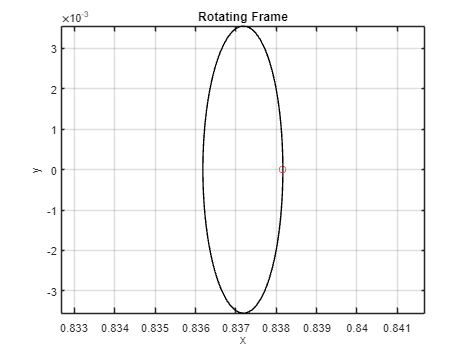

Tpo = 2 * t1;

tspan = 0:0.001 * Tpo:Tpo;

opts = odeset('AbsTol', 1e-8, 'RelTol', 1e-6);
[t, X] = ode45(@(t, X) prtbp(t, X), tspan, x0po, opts);

x = X(:, 1); 
y = X(:, 2);

plot(x, y, 'k', X0(1), X0(2), 'ro');
title('Rotating Frame'); 
xlabel('x'); ylabel('y');
axis equal; grid on;


X(end, :)' - x0po;

[x, t, phi_T, PHI] = PHIget(x0po, tfinal);
[V, D] = eig(phi_T);

D(1, 1)

ans = 2.6715e+03

D(2, 2)

ans = 3.7432e-04

D(3, 3)

ans = 1.0000 + 0.0008i

D(4, 4) 

ans = 1.0000 - 0.0008i

1 / D(1, 1)

ans = 3.7432e-04


Tpo / (2 * pi)

ans = 0.4285


e_stable = V(:, 4) / norm(V(:, 4));
displacement = -1.e-5;

x0 = x0po + displacement * e_stable;

tspan = 0:-0.001 * Tpo:-2 * Tpo;

opts = odeset('AbsTol', 1e-8, 'RelTol', 1e-6);
[t, X] = ode45(@(t, X) prtbp(t, X), tspan, x0, opts);
x = X(:, 1); 
y = X(:, 2);

plot(x, y, 'k', x0(1), x0(2), 'ro');

hold on

x0 = x0po + displacement * e_stable;

tspan = 0:0.001 * Tpo:1 * Tpo;
[t, X] = ode45(@(t, X) prtbp(t, X), tspan, x0, opts);
x = X(:, 1); 
y = X(:, 2);
plot(x, y, 'b', 1 - mu, 0, 'k*');


title('Rotating Frame'); 
xlabel('x'); ylabel('y');
axis equal; grid on;

displacement = 1e-3; % Start with a small displacement
X0 = XL + displacement * u; % Initial condition for the Lyapunov orbit
[x0po, Tpo] = liadifcor(X0);

attempt = 1

attempt = 2

attempt = 3

attempt = 4


title('Family of Lyapunov Orbits in Rotating Frame');
xlabel('x');
ylabel('y');
axis equal;
grid on;

% Parameters for displacement adjustment
displacement = 1e-3;  % Start with a small displacement
max_displacement = 4e-2; % Define maximum displacement
step_size = 1e-3;  % Step size for varying amplitude

% Set ODE solver options
opts = odeset('AbsTol', 1e-8, 'RelTol', 1e-6);

while displacement < max_displacement
    % New initial condition with increased displacement
    X0 = XL + displacement * u;
    
    % Apply differential correction
    [x0po, Tpo] = liadifcor(X0);
    
    % Set time span based on corrected period
    tspan = 0:0.001 * 2 * Tpo:2 * Tpo;
    
    % Integrate the periodic orbit using ode45
    [t, X] = ode45(@(t, X) prtbp(t, X), tspan, x0po, opts);
    
    % Extract positions
    x = X(:, 1);
    y = X(:, 2);
    
    % Plot the orbit in the rotating frame
    plot(x, y, 'k'); hold on;
    title('Family of LO'); 
    xlabel('x'); ylabel('y');
    axis equal; grid on;

    % Increase displacement for the next orbit
    displacement = displacement + step_size;
end

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 9

attempt = 10

attempt = 11

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 9

attempt = 10

attempt = 11

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 9

attempt = 10

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 9

attempt = 10

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 9

attempt = 10

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 9

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 9

attempt = 10

attempt = 11

attempt = 12

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 9

attempt = 10

attempt = 11

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 9

attempt = 10

attempt = 11

attempt = 12

attempt = 13

attempt = 14

attempt = 15

attempt = 16

attempt = 17

attempt = 18

attempt = 19

attempt = 20

attempt = 21

attempt = 22

attempt = 23

attempt = 24

attempt = 25

attempt = 26

ERROR = 'OCCURED'

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 9

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

attempt = 7

attempt = 8

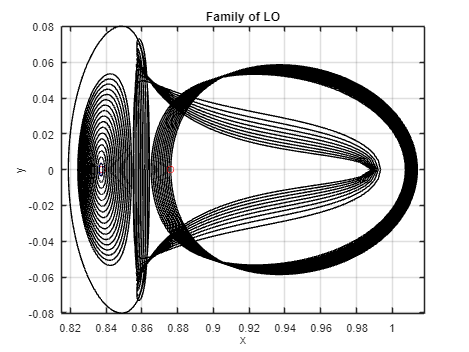


% Highlight initial point of last orbit
plot(X0(1), X0(2), 'ro');

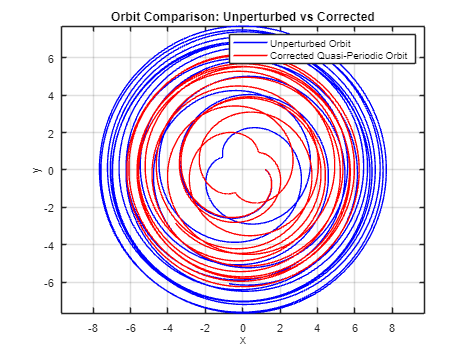


% Parameters for the system
mu = 0.0121505856;  % Earth-Moon system mass ratio
delta = 0.01;  % Small perturbation amplitude
tspan = [0 100];  % Time span for the integration
x0 = [1.2; 0; 0; 0];  % Initial conditions for Lyapunov orbit
options = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);  % ODE solver options

% Integrate the system without perturbation (Unperturbed Lyapunov orbit)
[t_unperturbed, sol_unperturbed] = ode45(@(t, x) cr3bp_equations(t, x, mu), tspan, x0, options);

% Apply Lindstedt-Poincaré correction for quasi-periodic orbit
corrected_sol = lindstedt_poincare_correction(sol_unperturbed, delta, mu, options, tspan);

% Plot the orbits (Unperturbed and Quasi-Periodic)
plot_orbits(sol_unperturbed, corrected_sol, t_unperturbed);


while displacement < max_displacement
    try
        X0 = XL + displacement * u;
        [x0po, Tpo] = liadifcor(X0);
        % Check for divergence
        if isnan(x0po)
            disp('Divergence detected, stopping continuation.');
            break;
        end
        ...
    catch ME
        disp(['Error occurred: ', ME.message]);
        break;
    end
    displacement = displacement + step_size;
end


function xdot = prtbp(t,x)

global mu

mu1=1-mu; % mass of larger  primary (nearest origin on left)
mu2=  mu; % mass of smaller primary (furthest from origin on right)

r3= ((x(1)+mu2)^2 + x(2)^2)^1.5;     % r: distance to m1, LARGER MASS
R3= ((x(1)-mu1)^2 + x(2)^2)^1.5;     % R: distance to m2, smaller mass

xdot    = zeros(4,1);
xdot(1) = x(3);
xdot(2) = x(4);
xdot(3) = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3)+2*x(4);
xdot(4) = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3)-2*x(3);
end


%% Compute 3-Body Energy

function E = energy(X,mu)

mu1=1-mu;mu2=mu;

Vsqrd= X(:,3).^2+X(:,4).^2 ;
Ubar = - mu1./sqrt((X(:,1)+mu2).^2+X(:,2).^2) ...
       - mu2./sqrt((X(:,1)-mu1).^2+X(:,2).^2) ...
       - 0.5*(X(:,1).^2+X(:,2).^2) - 0.5*mu1*mu2 ;

E = 0.5*Vsqrd + Ubar ;

end


function Xin = rot2iner(X,t,M,mu,del)

if nargin<=4
    del=0;
    if nargin<=3
        mu=0;
        if nargin<=2
            M=0;
        end
    end
end

if     M==1, d= -mu; 	% distance to LARGER  primary in CR3BP (M1)
elseif M==2, d=1-mu;	% distance to smaller primary in CR3BP (M2)
elseif M==0, d=0;	    % center-of-mass is the origin
end

c=cos(t + del); s=sin(t + del);

Xin=[];
Xin(:,1)= c.*(X(:,1)-d) - s.*X(:,2);
Xin(:,2)= s.*(X(:,1)-d) + c.*X(:,2);
Xin(:,3)=-s.*(X(:,1)+X(:,4)-d) + c.*(X(:,3) - X(:,2));
Xin(:,4)= c.*(X(:,1)+X(:,4)-d) + s.*(X(:,3) - X(:,2));

end




function [x0,t1] = liadifcor(x0g,show)

global mu

if nargin==1 
    show = 0; 
end

t0 = 0;
dxdot1 = 1;
MAXdxdot1 = 1.e-12; % measure of precision of perpendicular x-axis crossing
attempt = 0;
MAXattempt=25;

while abs(dxdot1) >  MAXdxdot1
	if attempt > MAXattempt
		ERROR = 'OCCURED'
		break
	end
		
	[t1,xx1]=find0(x0g); % find x-axis crossing
	attempt=attempt+1

    x1     = xx1(1); y1    = xx1(2);
    dxdot1 = xx1(3); ydot1 = xx1(4);

    [x,t,phi_t1,PHI]=PHIget(x0g,t1);

    if show==1,plotX(x);plot(a*x(1,1),a*x(1,2),'wo');
    axis([min(x(:,1)) max(x(:,1)) min(x(:,2)) max(x(:,2))]);
    axis('equal');end

	mu2 = 1 - mu;
	r1 = ((x1+mu)^2  + y1^2 );
	r2 = ((x1-mu2)^2 + y1^2 );
	rho1=1/r1^1.5;
	rho2=1/r2^1.5;
	
	omgx1=-(mu2*(x1+mu)*rho1) -(mu*(x1-mu2)*rho2) + x1;

	xdotdot1 = (2*ydot1 + omgx1);

	C1 = phi_t1(3,4);
	C2 = phi_t1(2,4);
	C3 = (C1 - (1/ydot1)*xdotdot1*C2);
	C4 = inv(C3)*(-dxdot1);
	dydot0 = C4;

	x0g(4) = x0g(4) + dydot0;
end
x0=x0g;

end


%% Compute the state transition matrix

function [x,t,phi_T,PHI]=PHIget(x0,tf)

global tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

N=length(x0);

PHI_0(1:N^2) 	   = reshape(eye(N),N^2,1);
PHI_0(1+N^2:N+N^2) = x0;

if     N==4 
    [t,PHI] = ode45(@(t,PHI) var2D(t,PHI), [0 tf], PHI_0, OPTIONS);
elseif N==6 
    [t,PHI] = ode45('var3D',[0 tf],PHI_0,OPTIONS); 
end

x = PHI(:,1+N^2:N+N^2); % trajectory

phi_T = reshape(PHI(length(t),1:N^2),N,N); % monodromy matrix, PHI(O,T)

end


%% For planar CR3BP, the variational equations

function PHIdot = var2D(t,PHI)

global FORWARD mu

mu1=1-mu;
mu2=  mu;

x(1:4) = PHI(17:20);
phi  = reshape(PHI(1:16),4,4);

r2= (x(1)+mu )^2 + x(2)^2;	% r: distance to m1, LARGER MASS
R2= (x(1)-mu1)^2 + x(2)^2;	% R: distance to m2, smaller mass
r3= r2^1.5; r5= r2^2.5;
R3= R2^1.5; R5= R2^2.5;

omgxx= 1+(mu1/r5)*(3*(x(1)+mu2)^2)+(mu2/R5)*(3*(x(1)-mu1)^2)-(mu1/r3+mu2/R3);
omgyy= 1+(mu1/r5)*(3* x(2)^2     )+(mu2/R5)*(3* x(2)^2     )-(mu1/r3+mu2/R3);
omgxy= 3*x(2)*     (mu1*(x(1)+mu2)/r5+mu2*(x(1)-mu1)/R5); 

	F     =[   0     0     1     0  ; 
	           0     0     0     1  ; 
		     omgxx omgxy   0     2  ; 
         	 omgxy omgyy  -2     0 ];

phidot = F * phi; % variational equation

PHIdot        = zeros(20,1);
PHIdot(1:16)  = reshape(phidot,16,1);
PHIdot(17)    = x(3);
PHIdot(18)    = x(4);
PHIdot(19)    = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3) + 2*x(4);
PHIdot(20)    = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3) - 2*x(3);
PHIdot(17:20) = FORWARD*PHIdot(17:20);

end


% Find an x-axis crossing

function [t1_z,x1_z]=find0(x0)
% function [t1_z,x1_z]=find0(x0)

global t0_z x0_z x1_zgl

tolzero = 1.e-10;
options = optimset('DiffMaxChange',tolzero,'TolCon',tolzero,'TolFun',tolzero) ;

t0_z = pi/2-.15;
[xx,~] = int(x0,t0_z);
x0_z=xx(end,:);
t1_z=fzero(@haloy,t0_z,options);
x1_z = x1_zgl;

clear global t0_z x0_z x1_zgl

end


% Integrate ODEs

function [x,t] = int(x0,tf)

global FORWARD tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

t0=0;
m=length(x0);

if     m==3	% surface of section--planar equations of motion integrated
	[t,x] = ode45('prtbp',[t0 tf],[x0(1) 0 x0(2) x0(3)],OPTIONS);
elseif m==4	% planar equations of motion integrated
    [t,x] = ode45(@(t,x) prtbp(t,x), [t0 tf], x0, OPTIONS) ;
elseif m==6	% 3D     equations of motion integrated
	[t,x] = ode45('rtbp' ,[t0 tf],x0,OPTIONS);
end
t=FORWARD*t;	% for backwards integration, time is like a countdown

end


function y1=haloy(t1)

global t0_z x0_z x1_zgl

if t1==t0_z
   x1_zgl = x0_z ; 
else
    [xx,tt]=intDT(x0_z,t0_z,t1);
    x1_zgl=xx(end,:);
end
y1    =x1_zgl(2);
end

function  [x,t] = intDT(x0,t0,tf)


global FORWARD tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

m=length(x0);

if m==4,     [t,x] = ode45(@(t,x) prtbp(t,x), [t0 tf], x0, OPTIONS) ;
elseif m==6, [t,x] = ode45('rtbp' ,[t0 tf],x0,OPTIONS);
end

t=FORWARD*t;	% for backwards integration, time is like a countdown

end
function dxdt = cr3bp_equations(~, x, mu)
    % CR3BP equations of motion
    r1 = sqrt((x(1) + mu)^2 + x(2)^2);
    r2 = sqrt((x(1) - 1 + mu)^2 + x(2)^2);
    
    dxdt = zeros(4, 1);
    dxdt(1) = x(3);
    dxdt(2) = x(4);
    dxdt(3) = x(1) + 2*x(4) - (1 - mu)*(x(1) + mu)/(r1^3) - mu*(x(1) - 1 + mu)/(r2^3);
    dxdt(4) = x(2) - 2*x(3) - (1 - mu)*x(2)/(r1^3) - mu*x(2)/(r2^3);
end

function corrected_sol = lindstedt_poincare_correction(sol_unperturbed, delta, mu, options, tspan)
    % Lindstedt-Poincaré method for frequency correction
    x_unperturbed = sol_unperturbed(:, 1);
    y_unperturbed = sol_unperturbed(:, 2);
    
    % Frequencies to introduce for quasi-periodic motion (multiple incommensurate frequencies)
    freq1 = 0.5;  % First frequency
    freq2 = 0.7;  % Second frequency (incommensurate with freq1)
    
    % Initialize perturbed solution
    corrected_sol = zeros(size(sol_unperturbed));

    % Perturb the x and y positions with multiple frequency components
    for i = 1:length(x_unperturbed)
        t = tspan(1) + (tspan(2) - tspan(1)) * i / length(x_unperturbed);  % Time scaling
        corrected_sol(i, 1) = x_unperturbed(i) + delta * sin(freq1 * t) + delta * sin(freq2 * t);
        corrected_sol(i, 2) = y_unperturbed(i) + delta * cos(freq1 * t) + delta * cos(freq2 * t);
    end

    % Apply differential correction using the corrected initial conditions
    x0_corrected = corrected_sol(1, :);
    [~, corrected_sol] = ode45(@(t, x) cr3bp_equations(t, x, mu), tspan, x0_corrected, options);
end


function plot_orbits(sol_unperturbed, corrected_sol, t_unperturbed)
    figure;
    plot(sol_unperturbed(:, 1), sol_unperturbed(:, 2), 'b', 'DisplayName', 'Unperturbed Orbit');
    hold on;
    plot(corrected_sol(:, 1), corrected_sol(:, 2), 'r', 'DisplayName', 'Corrected Quasi-Periodic Orbit');
    title('Orbit Comparison: Unperturbed vs Corrected');
    xlabel('x');
    ylabel('y');
    legend;
    axis equal;
    grid on;
end
